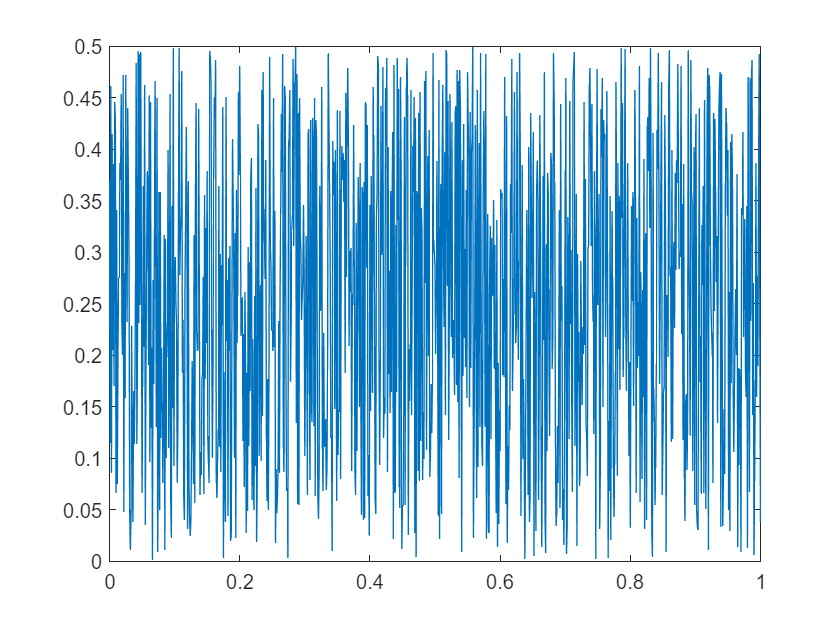

clear
fs=1000;
dt=1/fs;
t=0:dt:1;
%gaussian noise
f1=rand(1,length(t)).*0.5;
plot(t,f1);

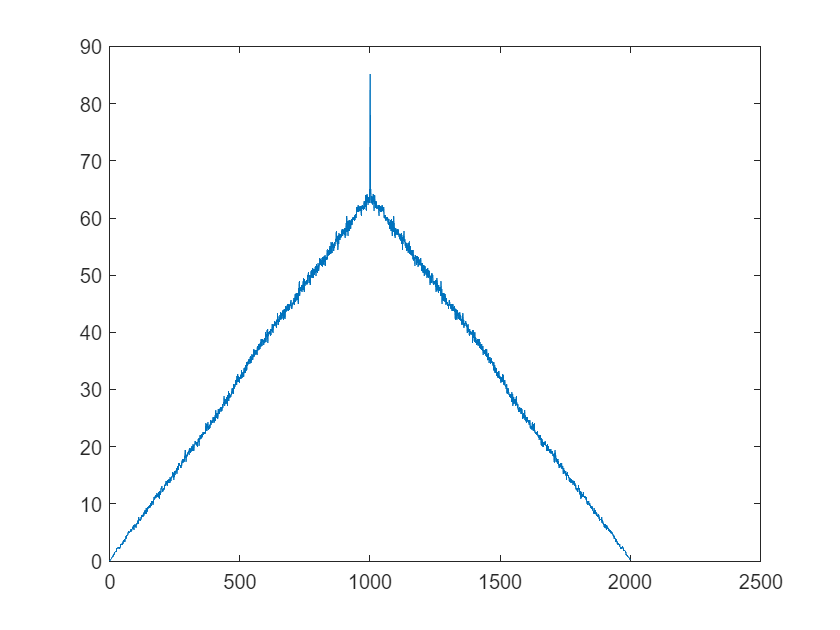

plot(xcorr(f1,f1))

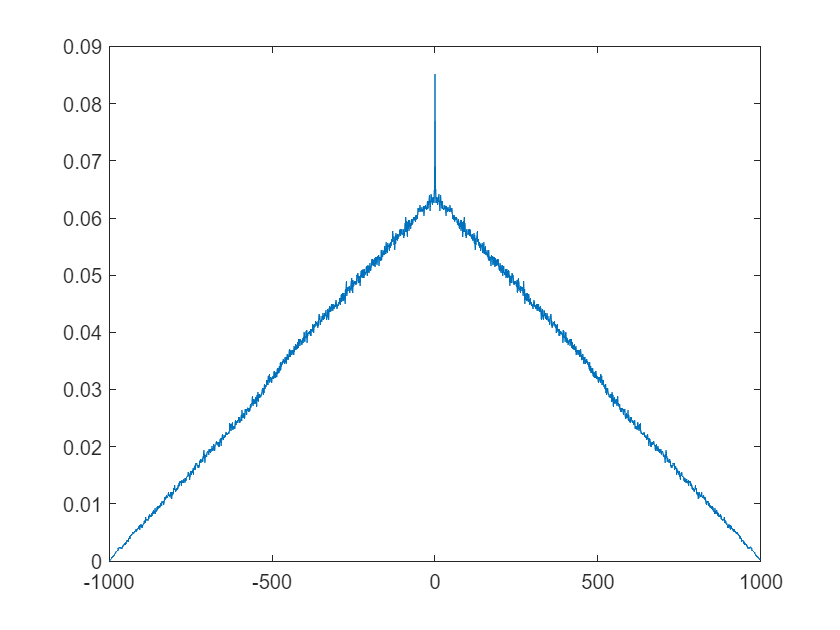

[C,lags] = xcorr(f1,'biased'); plot(lags,C);

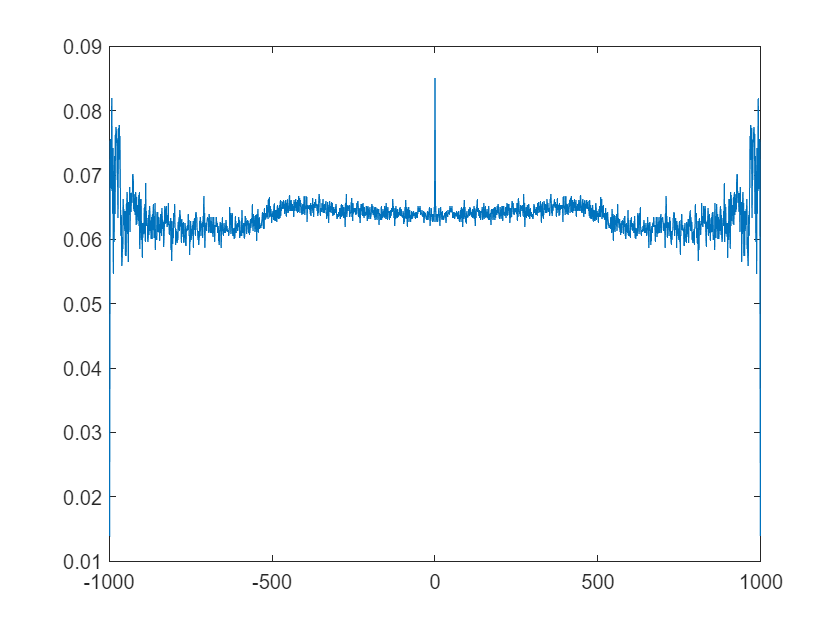

[C,lags] = xcorr(f1,'unbiased'); plot(lags,C);

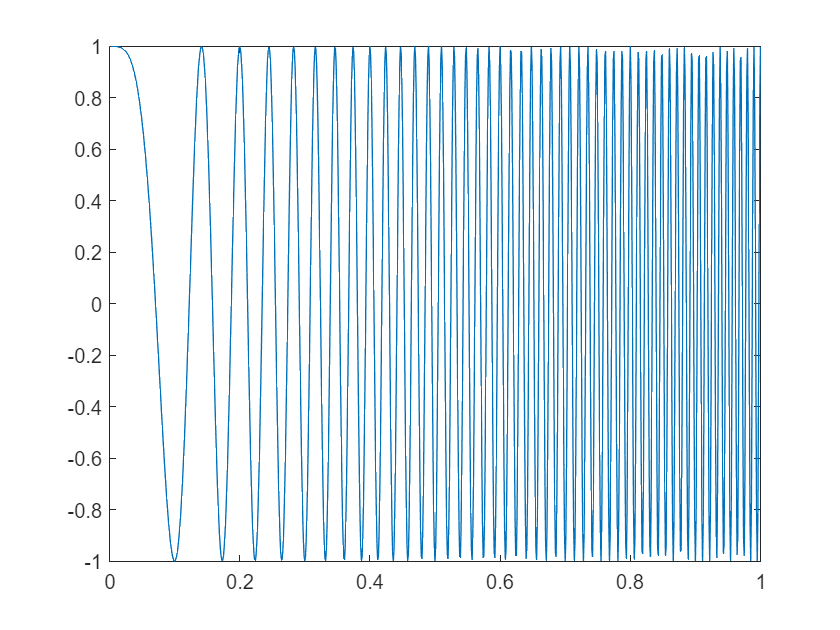

%chirp
f2=chirp(t,0,1);
plot(t,f2);

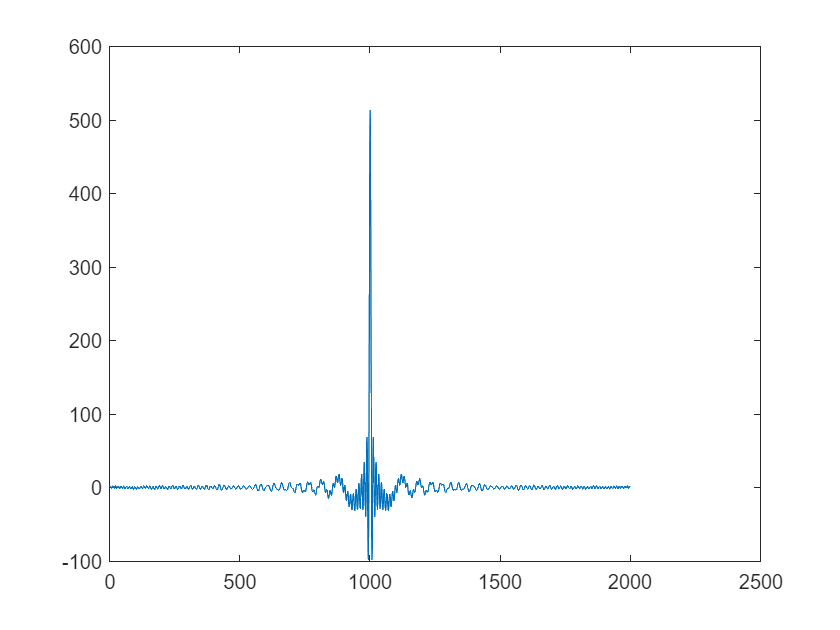

plot(xcorr(f2,f2))

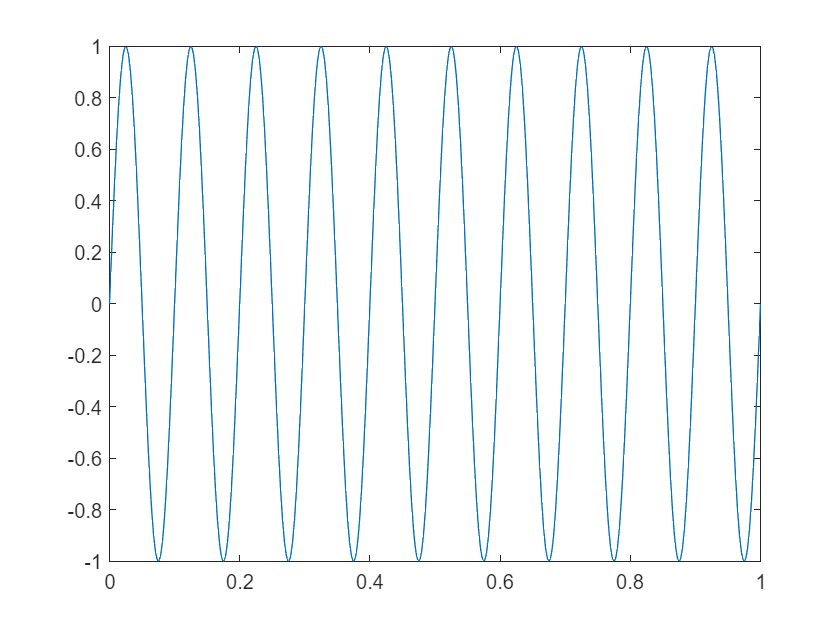

%sine
f3=sin(2*pi*10*t);
plot(t,f3);

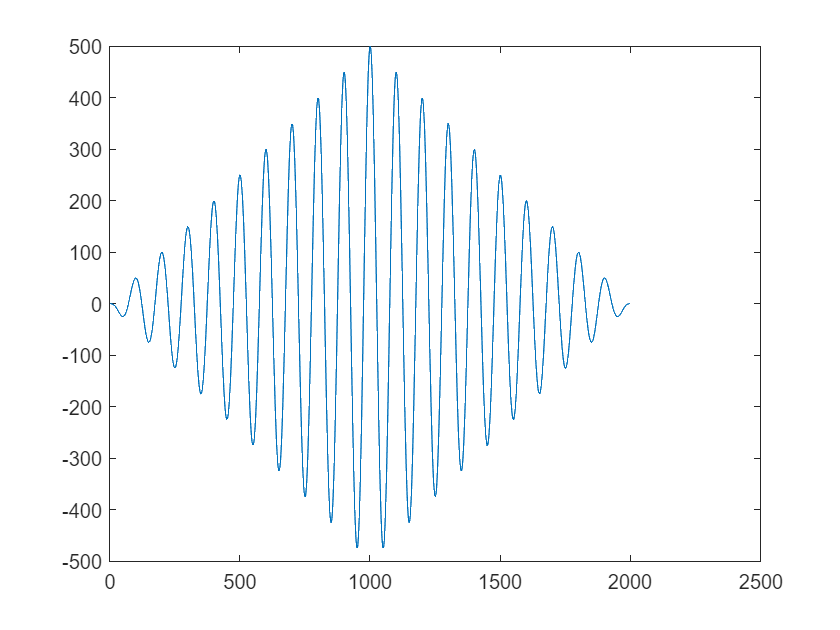

plot(xcorr(f3,f3))

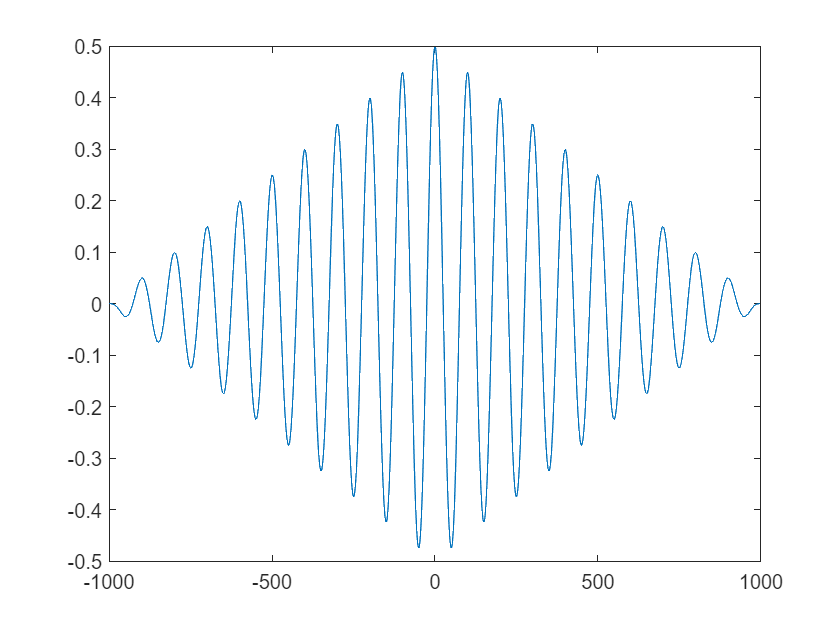

[C,lags] = xcorr(f3,'biased'); plot(lags,C);

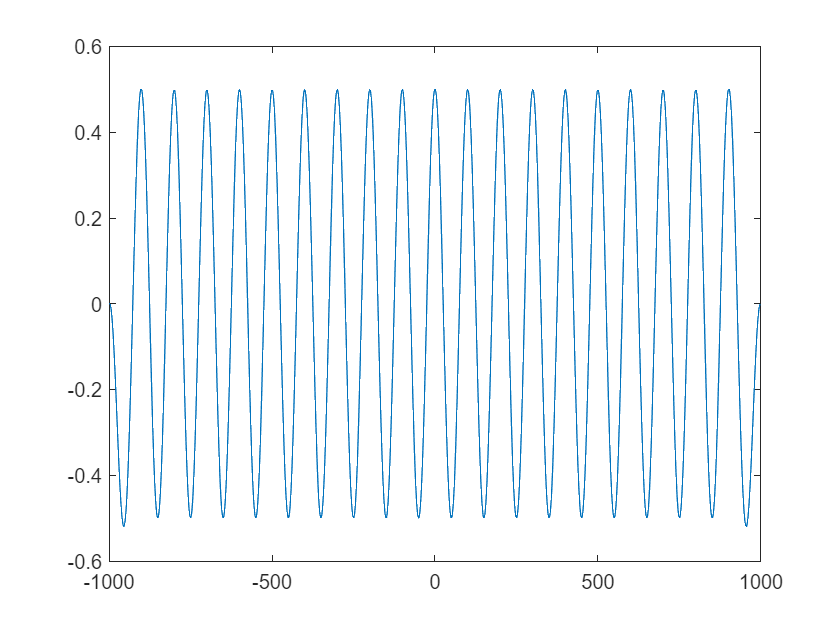

[C,lags] = xcorr(f3,'unbiased'); plot(lags,C);

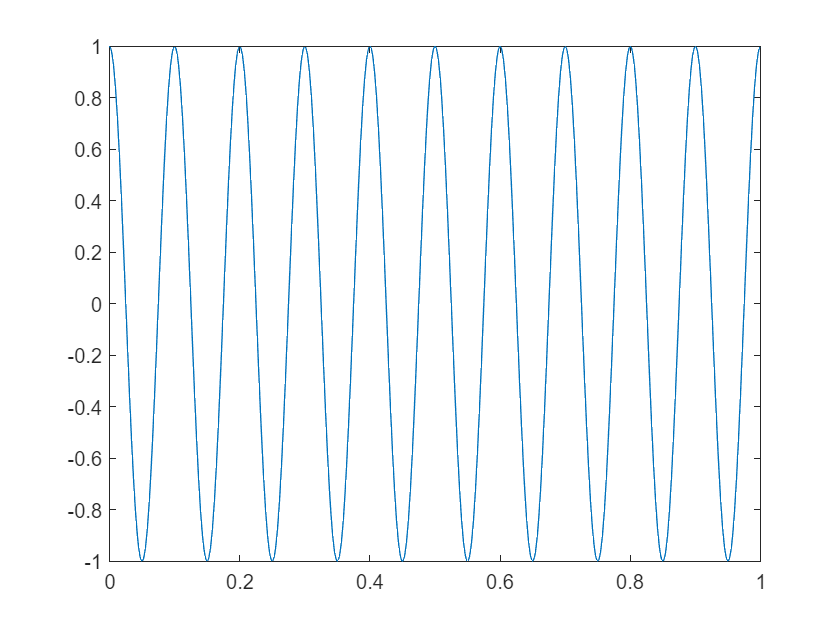

%cosine
f4=cos(2*pi*10*t);
plot(t,f4);

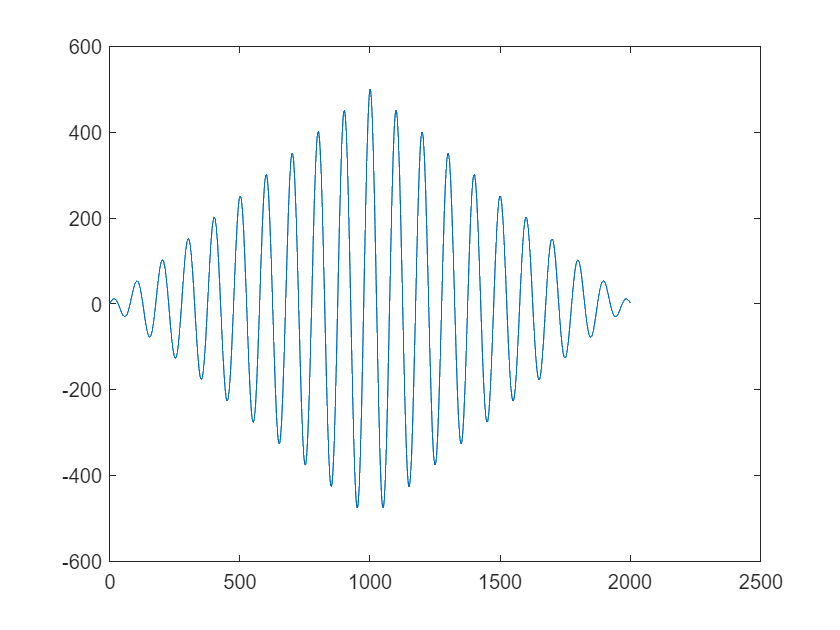

plot(xcorr(f4,f4))

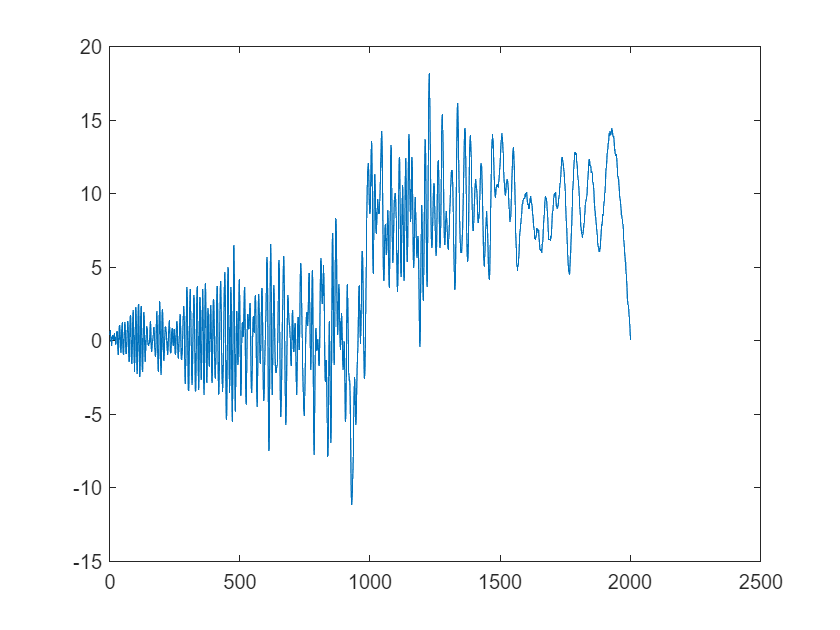


f12=xcorr(f1,f2);
plot(f12);

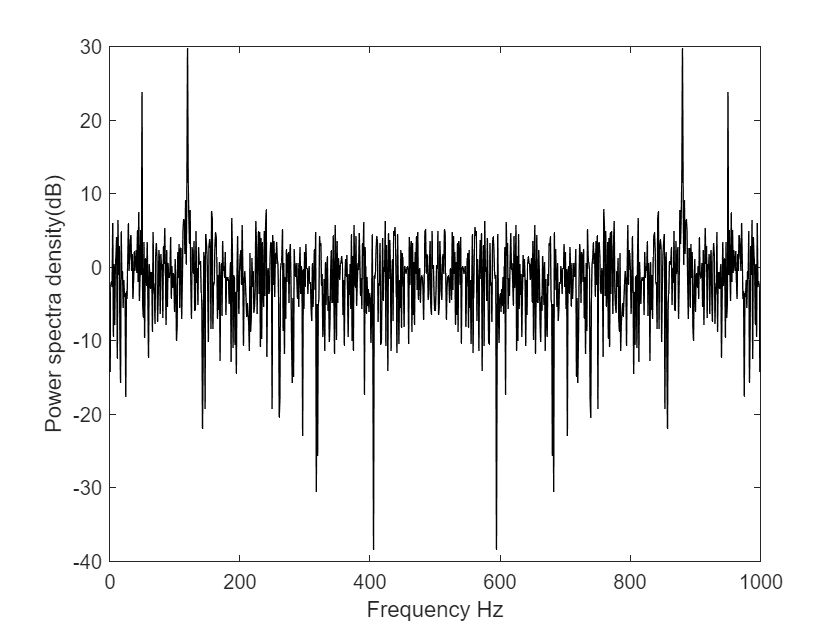

 
clear
fs=1000;
dt=1/fs;
t=0:dt:1;
f1=sin(2*pi*50*t)+2*sin(2*pi*120*t)+randn(size(t));

Pxx=abs(fft(f1)).^2/1001;
N=length(f1); df=fs/N; f=df*(0:N-1);
plot(f,10*log10(Pxx),'black')
xlabel('Frequency Hz'), ylabel('Power spectra density(dB)')


var(fft(f1))

ans = 3.5466e+03

var(fft(f1(1:500)))

ans = 1.7359e+03

var(fft(f1(1:250)))

ans = 830.6139

The longer the signal the higher the variance

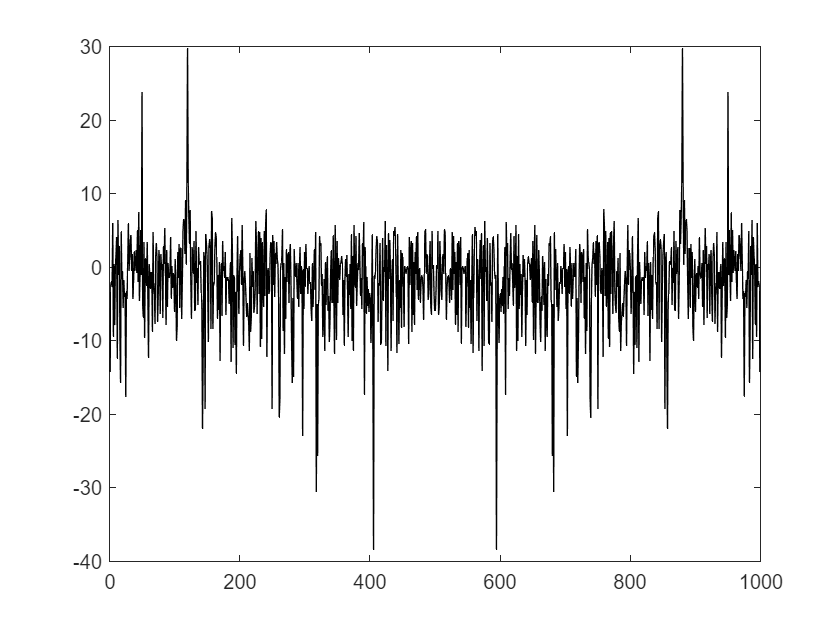

pxx=pwelch(f1,250);
plot(f,10*log10(Pxx),'black')